# Homework 3

## Problem 1 (20 Points)

Write a function `generate_gaussian_pyramid() `to generate the Gaussian pyramid from an image.  Your function should take an image as input, and return a cell array, containing the Gaussian pyramid levels. If the input image is an RGB image, use `rgb2gray()` to convert it to grayscale. Your function should repeatedly convolve the image with a Gaussian of  $\sigma=1$, and downsample it by throwing away ever other pixel.  in other words, the first level of the pyramid would be the original image, and each subsequent level would be the image reduced by a factor of 2 in each dimension.  The last level of the pyramid should have the width or height of 1.  You may use `imgaussfilt()` in your function.  You may not use `impyramid()` or `imresize()`.

Be sure to include the help comment in your function, and be sure to write unit tests for it.

Ideas for unit tests:

- What if the input image is empty: `generate_gaussian_pyramid([])`?

- What if the input image is 1x1: `generate_gaussian_pyramid(5)`?

- If the input image is 256x256, how many levels of the pyramid should there be?  What should be their sizes?

- If the input image is 640x480, how many levels of the pyramid should there be?

- Does your function work for an RGB image?  Note, the pyramid levels should still be grayscale.

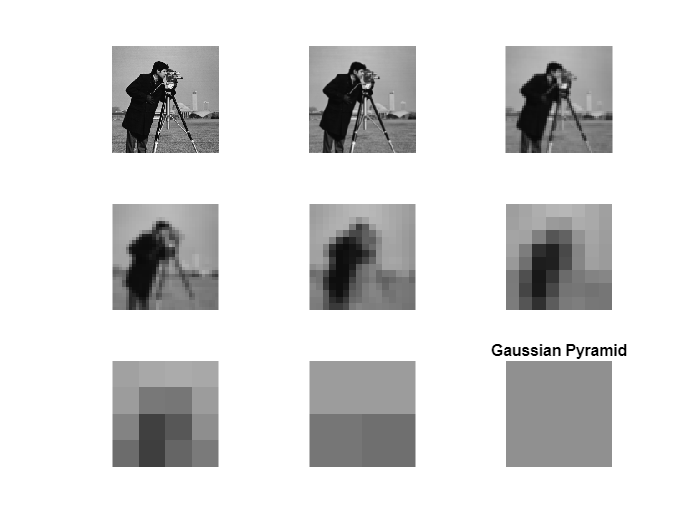

im = imread('cameraman.tif');
pyramid = generate_gaussian_pyramid(im);
figure;
for i = 1:numel(pyramid)
    subplot(3, 3, i);
    imshow(pyramid{i});
end
title('Gaussian Pyramid');

## Problem 2 (20 Points)

Write a function `[points1, points2] = match_points_KLT(im1, im2)` to track points from one image into another using the Kanade-Lucas-Tomasi algorithm.  The function should take two grayscale or RGB images.  `points1 `and `points2` should be Mx2 matrices containing coordinates of matching points. If either `im1` or `im2` are RGB images, use `rgb2gray()` to convert them to grayscale.  Use either `detectMinEigenFeatures()` or `detectHarrisFeatures()`  to detect the points in `im1. `Use `vision.PointTracker` to track the points from `im1 `into `im2.`

Be sure to include the help comment in your function, and be sure to write unit tests for it.

Ideas for unit tests:

- If one or both input images are empty, `points1` and `points2` should be empty.

- If one or both input images are blank (all 0's), `points1 `and` points2 `shoud be empty`.`

- What if `im1` and `im2` are the same image? `points1` and `points2` should be almost the same.  The difference should be less than a pixel.

## Problem 3 (20 Points)

Write a function `[points1, points2] = match_points_SIFT(im1, im2)` to match points between two images using SIFT features.  The function should take two grayscale or RGB images.  `points1 `and `points2` should be Mx2 matrices containing coordinates of matching points. If either `im1` or `im2` are RGB images, use `rgb2gray()` to convert them to grayscale.  Use `detectSIFTfeatures()` to detect the SIFT keypoints in both images.  Use `extractFeatures()` to extract the SIFT descriptors around the kyepoints.  Be sure to use the `validPoints` output of `extractFeatures()`, because there may be multiple SIFT descriptors for some of the SIFT keypoints.  Use `matchFeatures()` to match the features.  Check the documentation of `SIFTPoints` object returned by `detectSIFTfeatures()`.  You may need to use its `Location` property.

Be sure to include the help comment in your function, and be sure to write unit tests for it.

Ideas for unit tests:

- If one or both input images are empty, `points1` and `points2` should be empty.

- If one or both input images are blank (all 0's), `points1 `and` points2 `shoud be empty`.`

- What if `im1` and `im2` are the same image? `points1` and `points2` should be almost the same.  The difference should be less than a pixel.

## Example of Matching Points Using KLT and SIFT

Read in two images of the same scene.

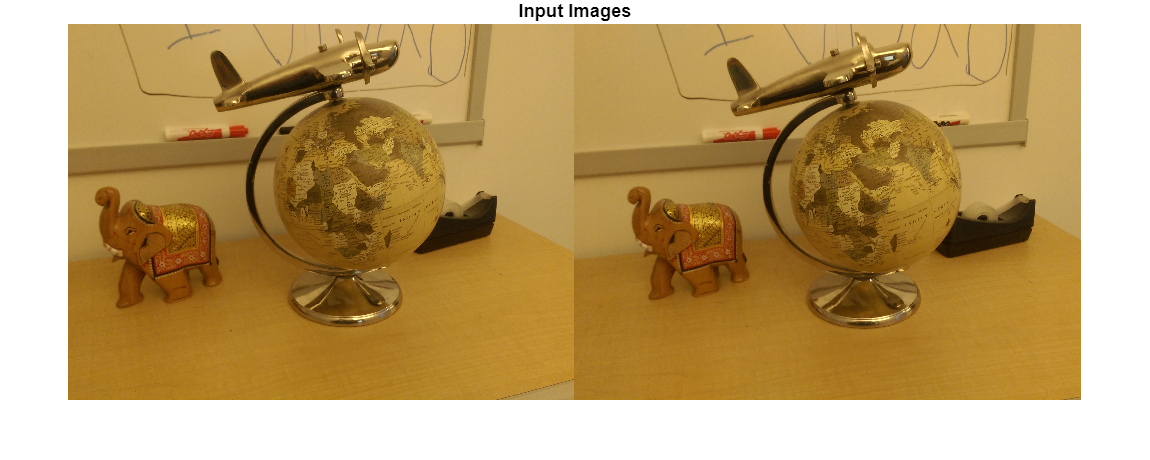

im1 = imread(fullfile(toolboxdir('vision'),'visiondata','upToScaleReconstructionImages', 'globe1.jpg'));
im2 = imread(fullfile(toolboxdir('vision'),'visiondata','upToScaleReconstructionImages', 'globe2.jpg'));
figure;
imshowpair(im1, im2, 'montage');
title('Input Images');

Track points from one image into the other using KLT.

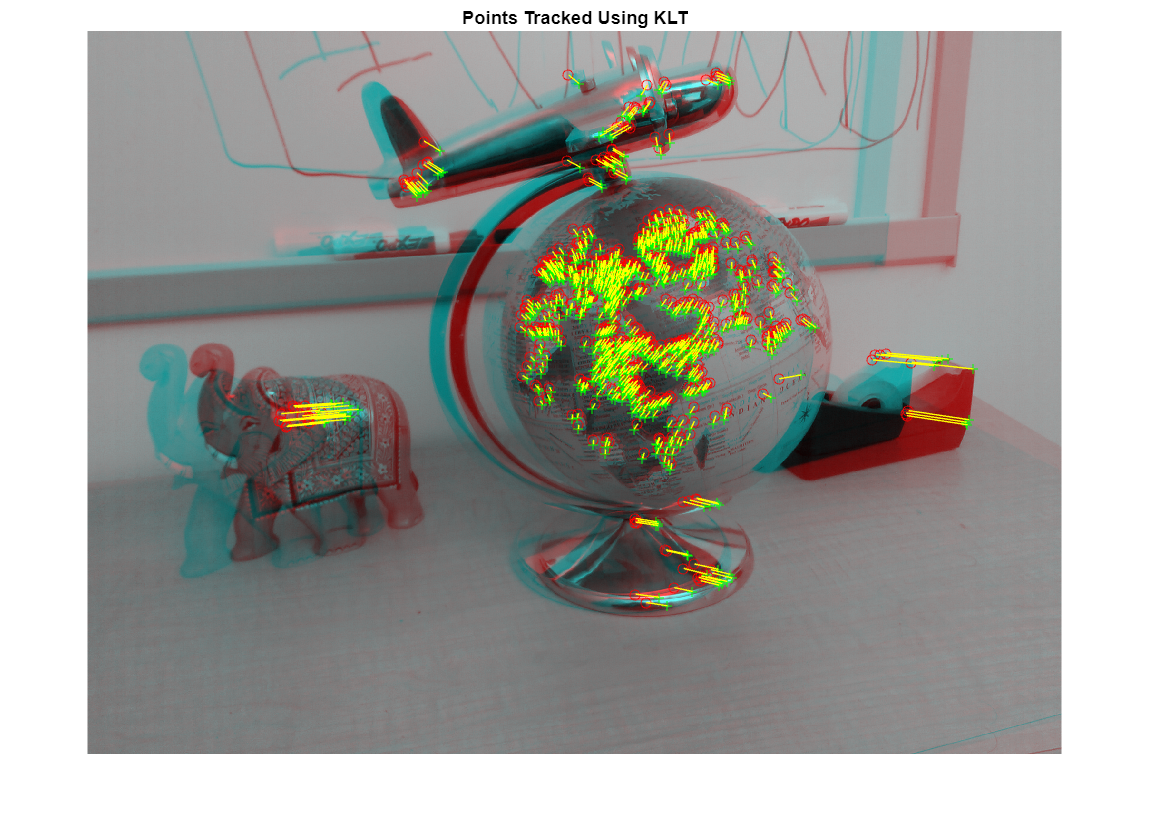

[points1, points2] = match_points_KLT(im1, im2);
showMatchedFeatures(im1, im2, points1, points2);
title('Points Tracked Using KLT');

Match points between the two images using SIFT features.

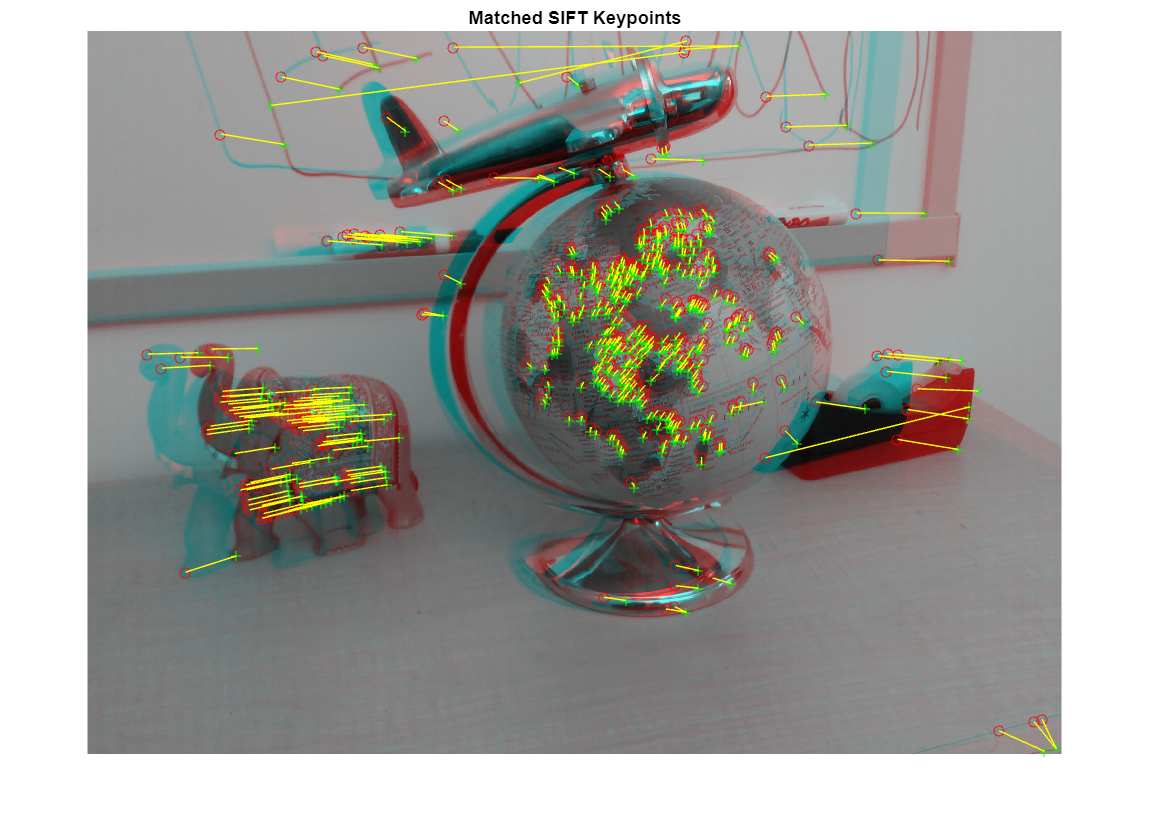

[points1, points2] = match_points_SIFT(im1, im2);
showMatchedFeatures(im1, im2, points1, points2);
title('Matched SIFT Keypoints');

## Reflection (10 pts)

Write a short document about what you have learned from this  assignment.  What did you find useful?  What was easy?  What was hard?   What was interesting?  The reflection should be included in your  hw1_<your_name> directory, as either a .pdf or .docx file.